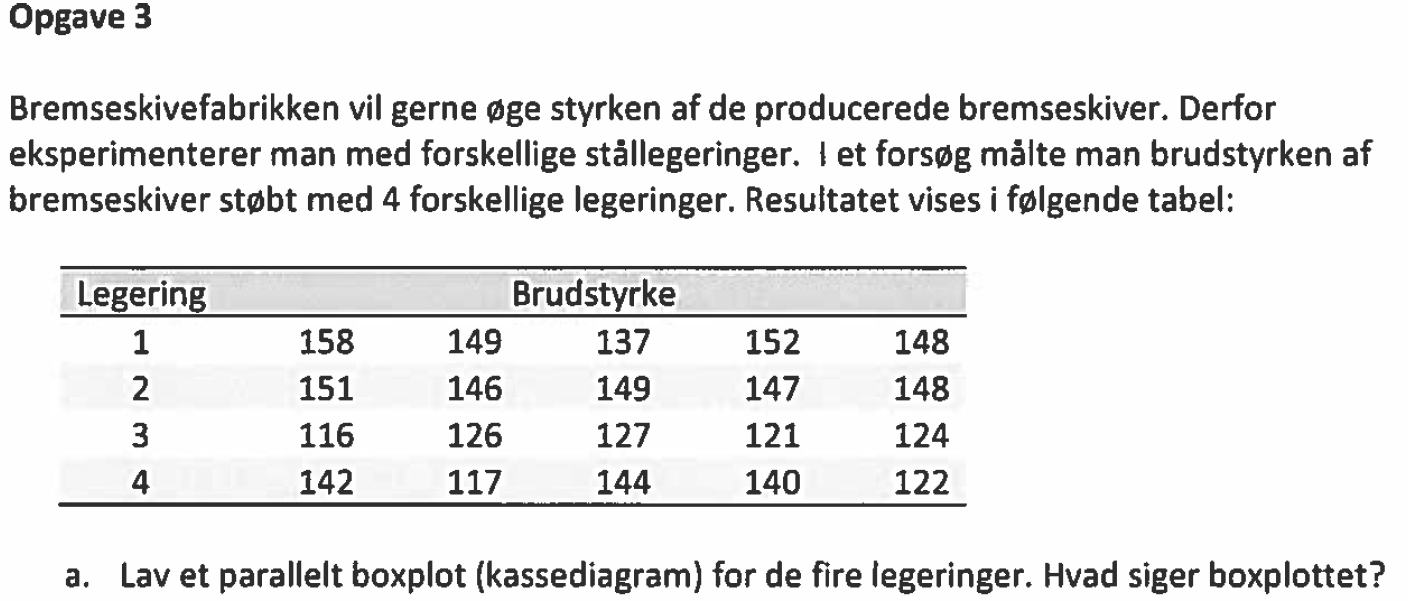

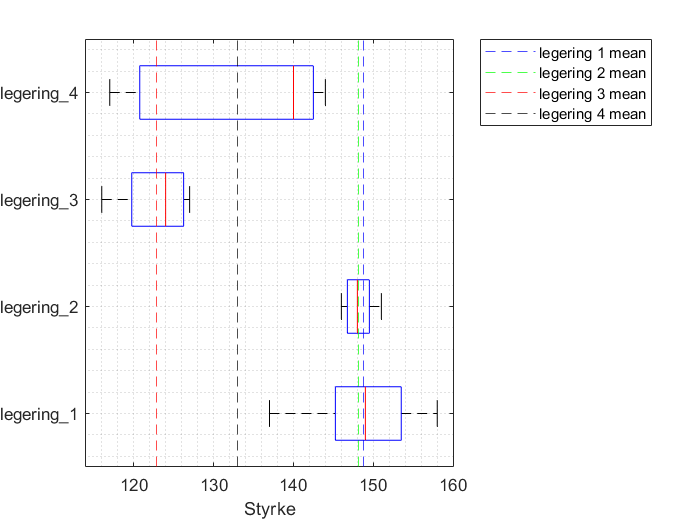

data = xlsread('M4STI_2015_data.xlsx');
legering_1 = data(1:5, 4);
legering_2 = data(6:10, 4);
legering_3 = data(11:15, 4);
legering_4 = data(16:20,4);

boxplot(data(1:20,4),data(1:20,3), 'Orientation','horizontal', ...
     "Labels", {'legering_1', 'legering_2', 'legering_3', 'legering_4'})
xline(mean(legering_1), '--b', 'DisplayName', 'legering 1 mean')
xline(mean(legering_2), '--g', 'DisplayName', 'legering 2 mean')
xline(mean(legering_3), '--r', 'DisplayName', 'legering 3 mean')
xline(mean(legering_4), '--k', 'DisplayName', 'legering 4 mean')
xlabel('Styrke')
legend('location', 'northeastoutside')
grid("minor")

Box plottet siger at legering 1 og 2 har størst styrke med en størrer spredning på legering 1

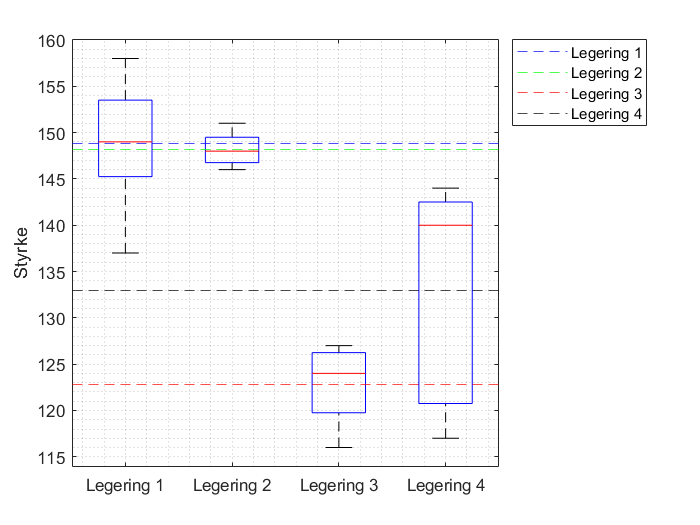

data = xlsread('M4STI_2015_data.xlsx');

n_start = 1; %første række af datapunkter
n_slut = 20; % sidste rækker af data
n_treat = 5; % antal data per forsøg
col = 4; % collonnen dataen er i
treatment = 3; % hvilket forsøg dataen tilhøre

labels = {'Legering 1', 'Legering 2', 'Legering 3', 'Legering 4'};


boxplot(data(n_start:n_slut,col),data(n_start:n_slut,treatment), ... % 'Orientation','horizontal',
         "Labels", labels)
colors = {'--b', '--g', '--r', '--k'};

for i = n_start:n_slut/n_treat
    yline(mean(data(n_start:n_start + n_treat - 1, col)), string(colors(i)), 'DisplayName', string(labels(i)))
    n_start = n_start + n_treat;
end

ylabel('Styrke')
legend('location', 'northeastoutside')
grid("minor")

format short
[p,table,stats] =  anova1(data(1:20,4), data(1:20,3), 'off')

p = 1.3051e-04

table = 4×6 cell array
    {'Source'}    {'SS'        }    {'df'}    {'MS'      }    {'F'       }    {'Prob>F'    }
    {'Groups'}    {[2.3828e+03]}    {[ 3]}    {[794.2667]}    {[ 13.2876]}    {[1.3051e-04]}
    {'Error' }    {[  956.4000]}    {[16]}    {[ 59.7750]}    {0×0 double}    {0×0 double  }
    {'Total' }    {[3.3392e+03]}    {[19]}    {0×0 double}    {0×0 double}    {0×0 double  }


stats = struct with fields:
    gnames: {4×1 cell}
         n: [5 5 5 5]
    source: 'anova1'
     means: [148.8000 148.2000 122.8000 133]
        df: 16
         s: 7.7314


Der er kraftig evidens for, at legeringerne ikke har samme styrke. P-værdien er 0.0001, langt under de 0.05, som var det valgte signifikansniveau.

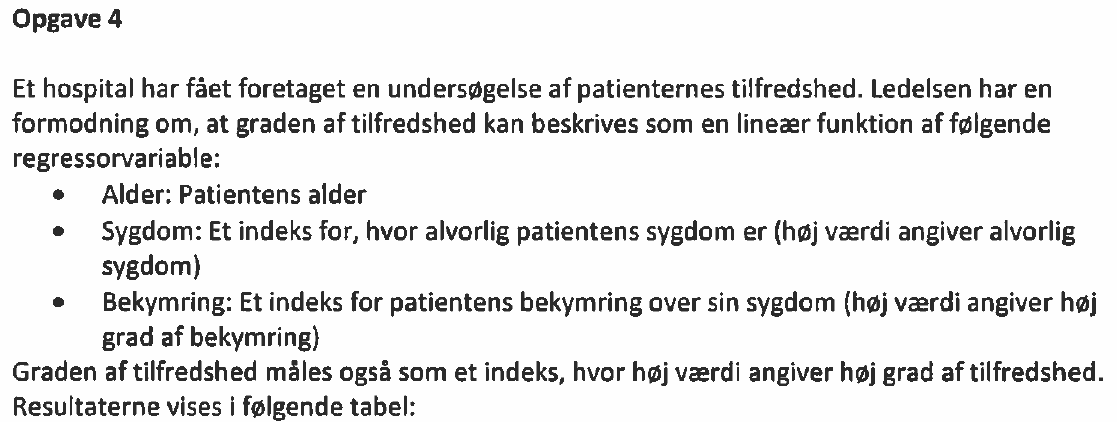

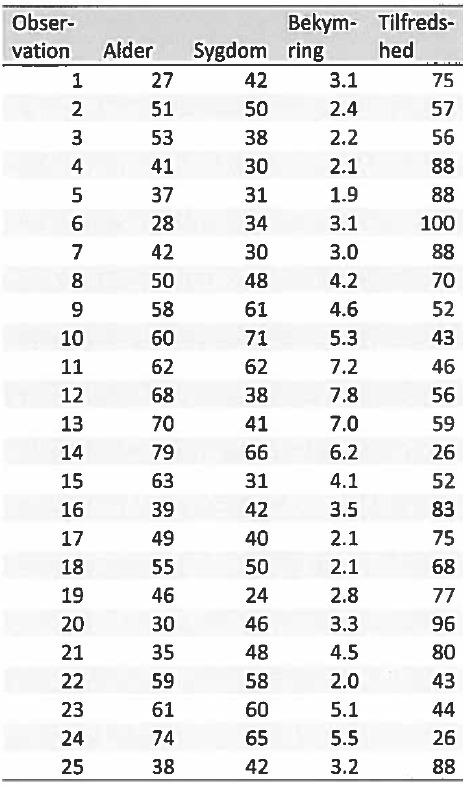

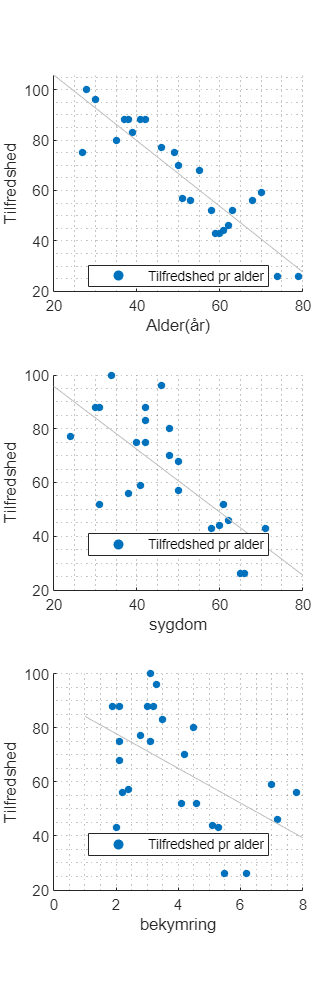

data = xlsread('M4STI_2015_data.xlsx');
alder = data(1:25, 6);
sygdom = data(1:25, 7);
bekym = data(1:25, 8);
Tilfreds = data(1:25,9);

figure('Position', [0 0 1500 4500])

subplot(3,1,1)
subtitle('Tilfredshed ift alder');
a = scatter(alder, Tilfreds, 20, 'filled', DisplayName='Tilfredshed pr alder');
lsline%(a, DisplayName='Forsommer')%(DisplayName='lsline forsommer');
% lsline;
xlabel('Alder(år)');
ylabel('Tilfredshed');
legend([a],Location="best")
grid('minor')

subplot(3,1,2)
subtitle('Tilfredshed ift alder');
a = scatter(sygdom, Tilfreds, 20, 'filled', DisplayName='Tilfredshed pr alder');
lsline%(a, DisplayName='Forsommer')%(DisplayName='lsline forsommer');
% lsline;
xlabel('sygdom');
ylabel('Tilfredshed');
legend([a],Location="best")
grid('minor')

subplot(3,1,3)
subtitle('Tilfredshed ift alder');
a = scatter(bekym, Tilfreds, 20, 'filled', DisplayName='Tilfredshed pr alder');
lsline%(a, DisplayName='Forsommer')%(DisplayName='lsline forsommer');
% lsline;
xlabel('bekymring');
ylabel('Tilfredshed');
legend([a],Location="best")
grid('minor')

mdl = fitlm([alder, sygdom, bekym], Tilfreds)

mdl = Linear regression model:
    y ~ 1 + x1 + x2 + x3

Estimated Coefficients:
                   Estimate      SE        tStat       pValue  
                   ________    _______    _______    __________

    (Intercept)      144.58     5.9902     24.137    8.4778e-17
    x1              -1.1267    0.13655    -8.2515    4.9959e-08
    x2             -0.58727    0.13246    -4.4335    0.00023049
    x3               1.3448     1.0668     1.2605        0.2213


Number of observations: 25, Error degrees of freedom: 21
Root Mean Squared Error: 7.07
R-squared: 0.901,  Adjusted R-Squared: 0.887
F-statistic vs. constant model: 64, p-value = 9.82e-11

Vi får således

Tilfredshed = 144.58 - 1.1267*Alder - 0.58727*Sygdom + 1.3448*Bekymring

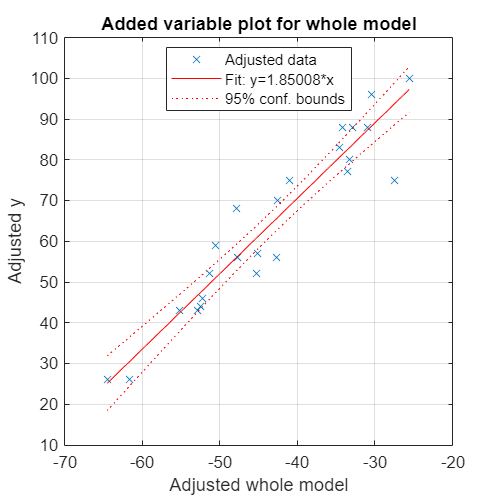

clf
figure('Position', [5 5 400 400])
plot(mdl)
grid

Tilfredshed = 144.58 - 1.1267*60 - 0.58727*45 + 1.3448*3.0

Tilfredshed = 54.5853

Tilfredsheden er således 55

Da vores 

R-adj værdi bliver 0,887 derfor virker dette til at være et nogenlunde fit.

p-værdieren er tæt på 0 for intercept og stiger imod x3 hvilket tilføje til at et godt fit med et stører bidrag fra x1 og x2

F-viser at mindst en variable har indflydelse på modellen hvis dette tal er under significat nivuet

genrelt passer moddel godt bortset fra for x3 (Bekymring). Her er p-værdien 0.2213, så denne koefficient er ikke signifikant forskellig fra 0.

Man kunne fjerne x3 (Bekymring) da den ser ud til at have meget lille indvirkning.

mdl = fitlm([alder, sygdom], Tilfreds)

mdl = Linear regression model:
    y ~ 1 + x1 + x2

Estimated Coefficients:
                   Estimate      SE        tStat       pValue  
                   ________    _______    _______    __________

    (Intercept)      144.01     6.0522     23.794    3.4318e-17
    x1               -1.038    0.11855    -8.7557     1.278e-08
    x2             -0.55818    0.13217    -4.2231    0.00034986


Number of observations: 25, Error degrees of freedom: 22
Root Mean Squared Error: 7.16
R-squared: 0.894,  Adjusted R-Squared: 0.884
F-statistic vs. constant model: 92.7, p-value = 1.91e-11

Det ses at modellen passer næsten lige så godt da R-adjust kun er anderledes på 3. decimal med 3.

mdl = fitlm([alder, sygdom, bekym], Tilfreds); 
[yhat, yci] = predict(mdl,[alder, sygdom, bekym]); % benyt de 3 x-værdier
estemat = yhat;
residual = Tilfreds - estemat;
KI_lav = yci(:,1);
KI_hoj = yci(:,2);
% [yhat,ypi] = predict(mdl,[alder, Tilfreds], 'Prediction','observation')	

table(alder, Tilfreds, estemat, residual, KI_lav, KI_hoj)

ans = 25×6 table
    alder    Tilfreds    estemat    residual    KI_lav    KI_hoj
    _____    ________    _______    ________    ______    ______

     27         75       93.665      -18.665    87.282    100.05
     51         57       60.984      -3.9838    56.211    65.757
     53         56       65.509      -9.5086    60.152    70.866
     41         88       83.593       4.4071    78.547    88.639
     37         88       87.244       0.7564    82.236    92.251
     28        100       97.236        2.764    91.265    103.21
     42         88       83.676       4.3235    78.978    88.375
     50         70       65.706       4.2944    62.612    68.799
     58         52       49.595       2.4048    45.016    54.175
     60         43        42.41      0.58954     35.76     49.0

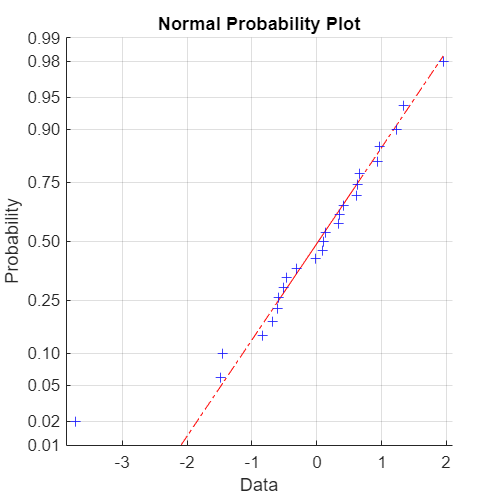

clf
rst = mdl.Residuals.Studentized; % en anden måde at få residualerne på
normplot(rst)

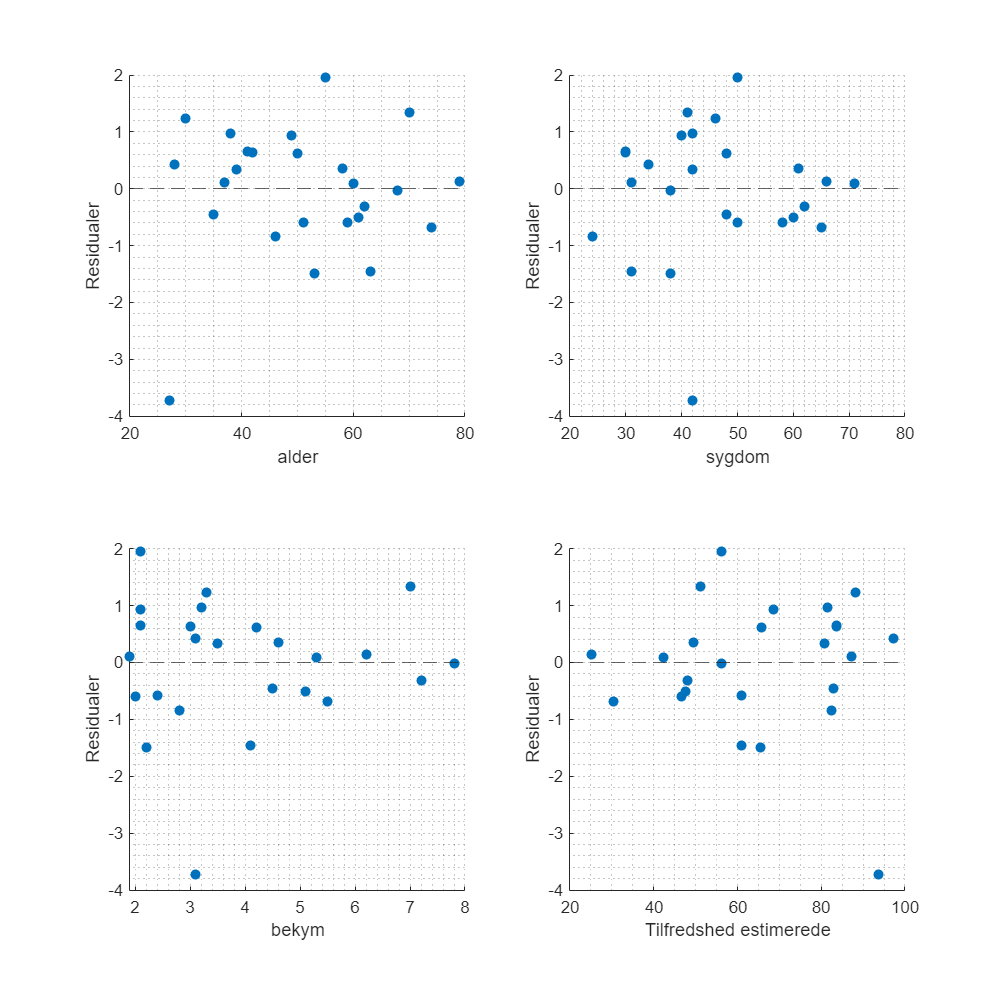

figure('Position', [0 0 800 800])
subplot(2,2,1)

scatter(alder, rst, 'filled') % , sygdom, bekym
yline(0, '--')
xlabel('alder')
ylabel('Residualer')
grid('minor')
subplot(2,2,2)
scatter(sygdom, rst, 'filled')
yline(0, '--')
xlabel('sygdom')
ylabel('Residualer')
grid('minor')

subplot(2,2,3)
scatter(bekym, rst, 'filled') % , , 
yline(0, '--')
xlabel('bekym')
ylabel('Residualer')
grid('minor')

subplot(2,2,4)
scatter(estemat, rst, 'filled')
yline(0, '--')
xlabel('Tilfredshed estimerede')
ylabel('Residualer')
grid('minor')

På residual plottet ses en reletiv tilfældig sprædning hvilket tyder på at modellen er rigtig.